# Problema 5 - Practic

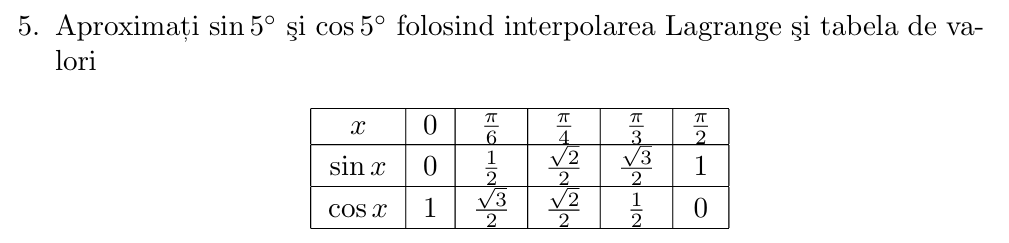

%PB1
function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

x_nodes = [0, pi/6, pi/4, pi/3, pi/2];
y_sin = [0, 1/2, sqrt(2)/2, sqrt(3)/2, 1];
y_cos = [1, sqrt(3)/2, sqrt(2)/2, 1/2, 0];

x_eval = deg2rad(5); % pi/36

[sin5, p_expr_sin] = lagrangeInterpolation(x_nodes, y_sin, x_eval);
[cos5, p_expr_cos] = lagrangeInterpolation(x_nodes, y_cos, x_eval);

fprintf('Aproximare sin(5°) = %.6f\n', sin5);

Aproximare sin(5°) = 0.086913


fprintf('Aproximare cos(5°) = %.6f\n', cos5);

Aproximare cos(5°) = 0.996386
